# Stability Switch and Oscillatory Dynamics

% Set default parameter values
Lambda = 0.0004;
mu = Lambda;
beta = 1;
gamma = 1;
alpha_i = 0;
epsilon = 0.5;
alpha_s = 0.2;

% Make parameter dictionary
par_keys = ["Lambda" "mu" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];
par_values = [Lambda mu beta gamma epsilon alpha_i alpha_s];
par_dictionary = dictionary(par_keys, par_values);


% Set up ODE options
tmin = 32000;
tmax = 40000;
tspan = [0 tmax];
solution_res = tmax - tmin + 1;
eval_times = linspace(tmin, tmax, solution_res);
i0 = 1e-2;
x0 = [1 - i0; i0; 0];
options = odeset("RelTol", 1e-12, "AbsTol", 1e-16);

% Allocate arrays
beta_vals = logspace(0, 2.4, 120);
Sp_time_series = cell(1, length(beta_vals));
I_time_series = cell(1, length(beta_vals));
I_max_values = zeros(1, length(beta_vals));
I_min_values = zeros(1, length(beta_vals));
EE_values = zeros(length(beta_vals), 3);
periods = zeros(1, length(beta_vals));

% For each beta value...
for i = 1:length(beta_vals)
    % Find the endemic equilibrium and its stability
    par_dictionary("beta") = beta_vals(i);
    EE = get_chadi_model_EE(par_dictionary);
    J_EE = chadi_jacobian(EE, par_dictionary);
    EE_values(i,:) = EE;
    EE_stable = all(real(eig(J_EE)) < 0);

    % If the EE is unstable...
    if not(EE_stable) && get_R0(par_dictionary) > 1
        % Simulate a trajectory
        odefun = @(t,x) chadi_model(t, x, par_dictionary);
        sol = ode89(odefun, tspan, x0, options);
        time_series = deval(sol, eval_times);

        % Find the period and save the last period of the solution
        [peaks, peak_locs] = findpeaks(time_series(2,:), "MinPeakHeight", 1e-3);
        periods(i) = int32(mean(diff(eval_times(peak_locs)))) + 1;
        Sp_time_series{i} = time_series(1,end - periods(i) + 1:end);
        I_time_series{i} = time_series(2,end - periods(i) + 1:end);
        I_max_values(i) = max(I_time_series{i});
        I_min_values(i) = min(I_time_series{i});
    else
        % If the EE is stable, the long-term dynamics are determined by the EE
        Sp_time_series{i} = EE(1);
        I_time_series{i} = EE(2);
        I_max_values(i) = max(0, EE(2));
        I_min_values(i) = max(0, EE(2));
        periods(i) = 1;
    end
    fprintf("%.1f%% Complete\r", i/length(beta_vals) * 100);
end

0.8% Complete
1.7% Complete
2.5% Complete
3.3% Complete
4.2% Complete
5.0% Complete
5.8% Complete
6.7% Complete
7.5% Complete
8.3% Complete
9.2% Complete
10.0% Complete
10.8% Complete
11.7% Complete
12.5% Complete
13.3% Complete
14.2% Complete
15.0% Complete
15.8% Complete
16.7% Complete
17.5% Complete
18.3% Complete
19.2% Complete
20.0% Complete
20.8% Complete
21.7% Complete
22.5% Complete
23.3% Complete
24.2% Complete
25.0% Complete
25.8% Complete
26.7% Complete
27.5% Complete
28.3% Complete
29.2% Complete
30.0% Complete
30.8% Complete
31.7% Complete
32.5% Complete
33.3% Complete
34.2% Complete
35.0% Complete
35.8% Complete
36.7% Complete
37.5% Complete
38.3% Complete
39.2% Complete
40.0% Complete
40.8% Complete
41.7% Complete
42.5% Complete
43.3% Complete
44.2% Complete
45.0% Complete
45.8% Complete
46.7% Complete
47.5% Complete
48.3% Complete
49.2% Complete
50.0% Complete
50.8% Complete
51.7% Complete
52.5% Complete
53.3% Complete
54.2% Complete
55.0% Complete
55.8% Complete
56.7% 

82.5% Complete


83.3% Complete
84.2% Complete
85.0% Complete
85.8% Complete
86.7% Complete
87.5% Complete
88.3% Complete
89.2% Complete
90.0% Complete
90.8% Complete
91.7% Complete
92.5% Complete
93.3% Complete
94.2% Complete
95.0% Complete
95.8% Complete
96.7% Complete
97.5% Complete
98.3% Complete
99.2% Complete
100.0% Complete


fprintf("\n");

I_time_series

I_time_series = 1×120 cell array
    {[-1.6010e-07]}    {[1.8010e-05]}    {[3.5357e-05]}    {[5.1918e-05]}    {[6.7730e-05]}    {[8.2827e-05]}    {[9.7241e-05]}    {[1.1100e-04]}    {[1.2414e-04]}    {[1.3669e-04]}    {[1.4867e-04]}    {[1.6011e-04]}    {1×848 double}    {1×947 double}    {1×1026 double}    {1×1080 double}    {1×1079 double}    {1×1052 double}    {1×1023 double}    {1×994 double}    {1×965 double}    {1×936 double}    {1×911 double}    {1×879 double}    {1×855 double}    {1×828 double}    {1×807 double}    {1×789 double}    {1×766 double}    {1×748 double}    {1×729 double}    {1×714 double}    {1×695 double}    {1×679 double}    {1×664 double}    {1×648 double}    {1×633 double}    {1×621 double}    {1×601 double}    {1×582 double}    {1×560 double}    {1×536 double}    {1×515 double}    {1×491 double}    {1×470 double}    {1×447 double}    {1×428 double}    {1×408 double}    {1×389 double}    {1×370 double}    {1×354 double}    {1×339 double}    {1×323 double}    {1×

## Plot 3D Oscillatory Dynamics

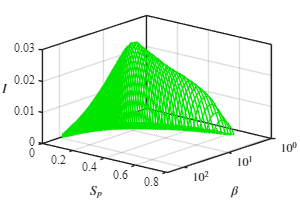

fig = figure("Position", [0 0 300 200]);
axis = axes(fig);

% Plot one cycle of Sp(t) and I(t) for each beta value
hold on;
for i = 1:length(beta_vals)
    plot3(log10(beta_vals(i))*ones(1, periods(i)), Sp_time_series{i}, I_time_series{i}, "Color", [0 0.9 0], "LineWidth", 0.5);
end

view(-230, 26);

xlabel("$\beta$", "Interpreter", "latex", "Rotation", 0);
ylabel("$S_p$", "Interpreter", "latex", "Rotation", 0);
zlabel("$I\quad$", "Interpreter", "latex", "Rotation", 0);

xticks([0 1 2]);
xticklabels(["$10^0$" "$10^1$" "$10^2$"]);
ylim([0, 0.81]);
zlim([0, 0.03]);

axis.XAxis.TickLabelInterpreter = "latex";
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.FontName = "Times New Roman";
axis.ZAxis.FontName = "Times New Roman";

grid on;
box on;
axis.LineWidth = 0.33;

theme(fig, "light");

exportgraphics(fig, "oscillatory_switch_3D.pdf", "Resolution", "600");

## Plot 2D Oscillatory Dynamics

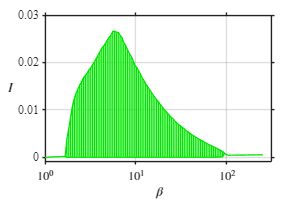

fig = figure("Position", [0 0 300 200]);
axis = axes(fig);

% Plot vertical lines to show the range of I(t) over one period
hold on;
for i = 1:length(beta_vals)
    plot(log10([beta_vals(i), beta_vals(i)]), [I_min_values(i), I_max_values(i)], "HandleVisibility", "off", "Color", [0 0.9 0], "LineWidth", 1);
end

% Plot the maximum and minimum values of I(t) over one period
plot(log10(beta_vals), I_max_values, "DisplayName", "$I_\mathrm{max}$", "Color", [0 0.9 0], "LineWidth", 1);
plot(log10(beta_vals), I_min_values, "DisplayName", "$I_\mathrm{min}$", "Color", [0 0.9 0], "LineWidth", 1);

xlabel("$\beta$", "Interpreter", "latex", "Rotation", 0);
ylabel("$I$", "Interpreter", "latex", "Rotation", 0);
ylim([-0.001, 0.03]);
xticks([0 1 2]);
xticklabels(["$10^0$" "$10^1$" "$10^2$"]);

axis.XAxis.TickLabelInterpreter = "latex";
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.FontName = "Times New Roman";

grid on;
box on;
axis.LineWidth = 0.33;
set(axis, 'TickDir', 'out');

theme(fig, "light");

exportgraphics(fig, "oscillatory_switch_2D.pdf", "Resolution", "600");

## Plot Eigenvalue at the EE

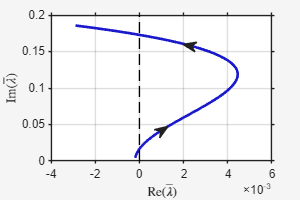

beta_vals_subset = beta_vals(2:end-16); % Take a subset of the beta values to frame the plot better

% Allocate space to store the eigenvalues
J_eigenvalues = zeros(3, length(beta_vals_subset));

fig = figure("Position", [0 0 300 200]);
axis = axes(fig);

% For each beta value, find the eigenvalues of the jacobian at the EE
for i = 1:length(beta_vals_subset)
    par_dictionary("beta") = beta_vals_subset(i);
    EE = get_chadi_model_EE(par_dictionary);
    J_EE = chadi_jacobian(EE, par_dictionary);
    J_eigenvalues(:,i) = eig(J_EE);
end

% Get the real and imaginary parts of the first eigenvalue
real_parts = real(J_eigenvalues(1,:));
imag_parts = imag(J_eigenvalues(1,:));

hold on;
plot(real(J_eigenvalues(1,:)), imag(J_eigenvalues(1,:)), "Color", [0.1 0.1 0.8], "LineWidth", 2);
plot([0,0], [0,0.2], "Color", [0 0 0], "LineStyle", "--");

% Add arrows
annotation('arrow', [0.55 0.56], [0.358 0.368]);
annotation('arrow', [0.62 0.61], [0.775 0.778]);

xlabel("$\mathrm{Re}(\bar\lambda)$", "Interpreter", "latex");
ylabel("$\mathrm{Im}(\bar\lambda)$", "Interpreter", "latex");

grid on;
box on;
axis.LineWidth = 0.33;
set(axis, 'TickDir', 'out');

theme(fig, "light");

exportgraphics(fig, "jacobian_eigenvalue.pdf", "Resolution", "600");

# Hopf Surface

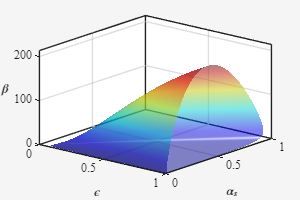

Lambda = 0.0004;
mu = Lambda;
gamma = 1;
alpha_i = 0;

% Get the hopf surface function
H = @(epsilon, alpha_s, beta) Hopf_surface(Lambda, mu, beta, gamma, epsilon, alpha_i, alpha_s);

% Evaluate H at all points on a 3D grid
num_epsilon_vals = 128;
num_alpha_s_vals = 128;
num_beta_vals = 512;
[x, y, z] = meshgrid(linspace(0, 1, num_epsilon_vals), linspace(0, 1, num_alpha_s_vals), linspace(0, 250, num_beta_vals));
V = H(x, y, z);

% Generate the isosurface where H equals zero
surf = isosurface(x, y, z, V, 0);

% Extract Z-coordinates of vertices
z_coords = surf.vertices(:,3);

% Map Z-coordinates to colormap
cm = jet(256); % Choose your colormap (e.g., jet, parula, hot)
c_min = min(z_coords);
c_max = max(z_coords);
c_index = round((z_coords - c_min) / (c_max - c_min) * 255) + 1;
surf.facevertexcdata = cm(c_index,:);

% Plot the patch object
fig = figure("Position", [0 0 300 200]);
axis = axes(fig);
p = patch(surf, 'FaceColor', 'interp', 'EdgeColor', 'none');

% 4. Format the plot for better visibility
isonormals(x, y, z, V, p);
p.EdgeColor = 'none';
p.FaceAlpha = 0.5;
p.AmbientStrength = 0.67;
view(40, 26);
camlight; 
lighting gouraud;
xlabel("$\epsilon$", "Interpreter", "latex", "Rotation", 0); 
ylabel("$\alpha_s$", "Interpreter", "latex", "Rotation", 0); 
zlabel("$\beta\quad$", "Interpreter", "latex", "Rotation", 0);

axis.XAxis.FontName = "Times New Roman";
axis.YAxis.FontName = "Times New Roman";
axis.ZAxis.FontName = "Times New Roman";

grid on;
box on;
axis.LineWidth = 0.33;

theme(fig, "light");

exportgraphics(fig, "hopf_surface.pdf", "Resolution", "300");

# Helper Functions

% Returns H defined in the main text
function H = Hopf_surface(Lambda, mu, beta, gamma, epsilon, alpha_i, alpha_s)
    % Hardcoded equations for the endemic equilibrium from the Supplemental Material of Saad-Roy et al. (2023)
    A2 = -epsilon.*beta.*(mu + alpha_i);
    A1 = Lambda.*epsilon.*beta + epsilon.*gamma.*mu - ((mu + gamma + alpha_i) ./ beta) .* (beta.*(alpha_s + mu) + epsilon.*beta.*mu);
    A0 = Lambda.*(alpha_s + mu) - ((mu + gamma + alpha_i) ./ beta) .* mu.*(alpha_s + mu);

    I = (-A1 - sqrt(A1.^2 - 4.*A0.*A2)) ./ (2.*A2);
    Ss = (gamma.*I) ./ (epsilon.*beta.*I + alpha_s + mu);

    % Return H
    term1 = epsilon.*alpha_s.*(mu + alpha_s).*beta.*Ss;
    term2 = ((epsilon.*beta.*I + mu + alpha_s).^2).*(beta.*I + mu);
    term3 = (epsilon.*beta.*I + mu + beta.*I).*(1 - epsilon).*(mu + alpha_s).*beta.*Ss;
    term4 = (epsilon.*beta.*I + mu + alpha_s).*((beta.*I + mu).^2);
    term5 = (beta.*I + mu).*(mu + alpha_i).*beta.*I;
    H = term1 - term2 - term3 - term4 - term5;
end

% Returns the mass-action model from Saad-Roy et al. (2023)
function dx_dt = chadi_model(t, x, par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    dSp_dt = Lambda - beta*Sp*I - mu*Sp;
    dI_dt = beta*Sp*I + epsilon*beta*Ss*I - (gamma + mu + alpha_i)*I;
    dSs_dt = gamma*I - epsilon*beta*Ss*I - (mu + alpha_s)*Ss;

    dx_dt = [dSp_dt; dI_dt; dSs_dt];
end

% Returns the location of the endeimc equilibrium analytically using the
% equations in the Supplemental Material of Saad-Roy et al. (2023)
function x_star = get_chadi_model_EE(par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    A2 = -epsilon*beta*(mu + alpha_i);
    A1 = Lambda*epsilon*beta + epsilon*gamma*mu - (mu + gamma + alpha_i)/beta * (beta*(alpha_s + mu) + epsilon*beta*mu);
    A0 = Lambda*(alpha_s + mu) - (mu + gamma + alpha_i)/beta * mu*(alpha_s + mu);

    I_star = (-A1 - sqrt(A1^2 - 4*A0*A2)) / (2*A2);
    Ss_star = gamma*I_star / (epsilon*beta*I_star + alpha_s + mu);
    Sp_star = (mu + gamma + alpha_i)/beta - epsilon*Ss_star;

    x_star = [Sp_star; I_star; Ss_star];
end

% Returns the Jacobian of the mass-action model from Saad-Roy et al. (2023)
function J = chadi_jacobian(x, par_dictionary)
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    J = [[-beta*I - mu, -beta*Sp, 0];
        [beta*I, beta*Sp + epsilon*beta*Ss - (gamma + mu + alpha_i), epsilon*beta*I];
        [0, gamma - epsilon*beta*Ss, -epsilon*beta*I - (mu + alpha_s)]];
end

function R0 = get_R0(par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    R0 = (Lambda / mu) * (beta / (gamma + mu + alpha_i));
end